# I-F curve, count spikes

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


t = c001_Time*1000;
in = [c002_Membrane_Voltage_1; c003_Membrane_Voltage_1; c004_Membrane_Voltage_1; c005_Membrane_Voltage_1; c006_Membrane_Voltage_1; c007_Membrane_Voltage_1; c008_Membrane_Voltage_1; c009_Membrane_Voltage_1; c010_Membrane_Voltage_1; c011_Membrane_Voltage_1]*1000;
%in = [c002_Membrane_Voltage_2; c003_Membrane_Voltage_2; c004_Membrane_Voltage_2; c005_Membrane_Voltage_2; c006_Membrane_Voltage_2; c007_Membrane_Voltage_2; c008_Membrane_Voltage_2; c009_Membrane_Voltage_2; c010_Membrane_Voltage_2; c011_Membrane_Voltage_2]*1000;

clear c002_Membrane_Voltage_1 c003_Membrane_Voltage_1 c004_Membrane_Voltage_1 c005_Membrane_Voltage_1 c006_Membrane_Voltage_1 c007_Membrane_Voltage_1 c008_Membrane_Voltage_1 c009_Membrane_Voltage_1 c010_Membrane_Voltage_1 c011_Membrane_Voltage_1
%clear c002_Membrane_Voltage_2 c003_Membrane_Voltage_2 c004_Membrane_Voltage_2 c005_Membrane_Voltage_2 c006_Membrane_Voltage_2 c007_Membrane_Voltage_2 c008_Membrane_Voltage_2 c009_Membrane_Voltage_2 c010_Membrane_Voltage_2 c011_Membrane_Voltage_2




## plot voltage responses

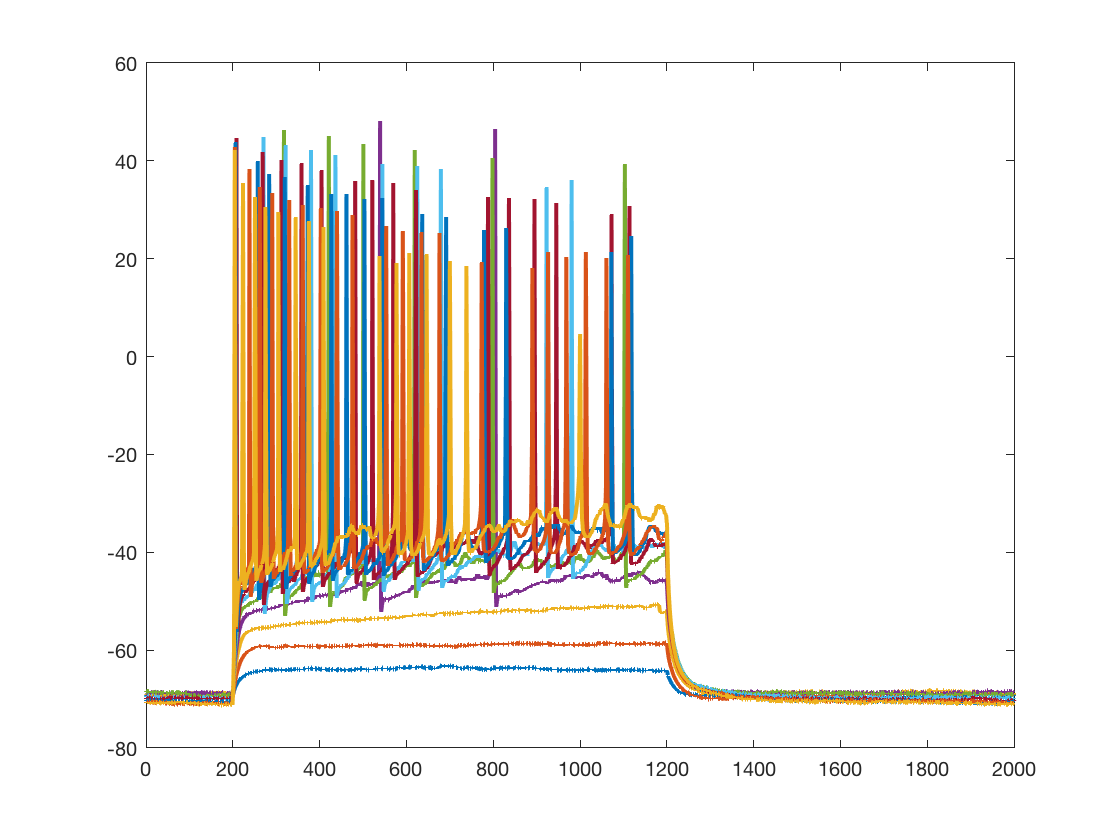


 
figure;             
plot(t,in,'LineWidth',2);

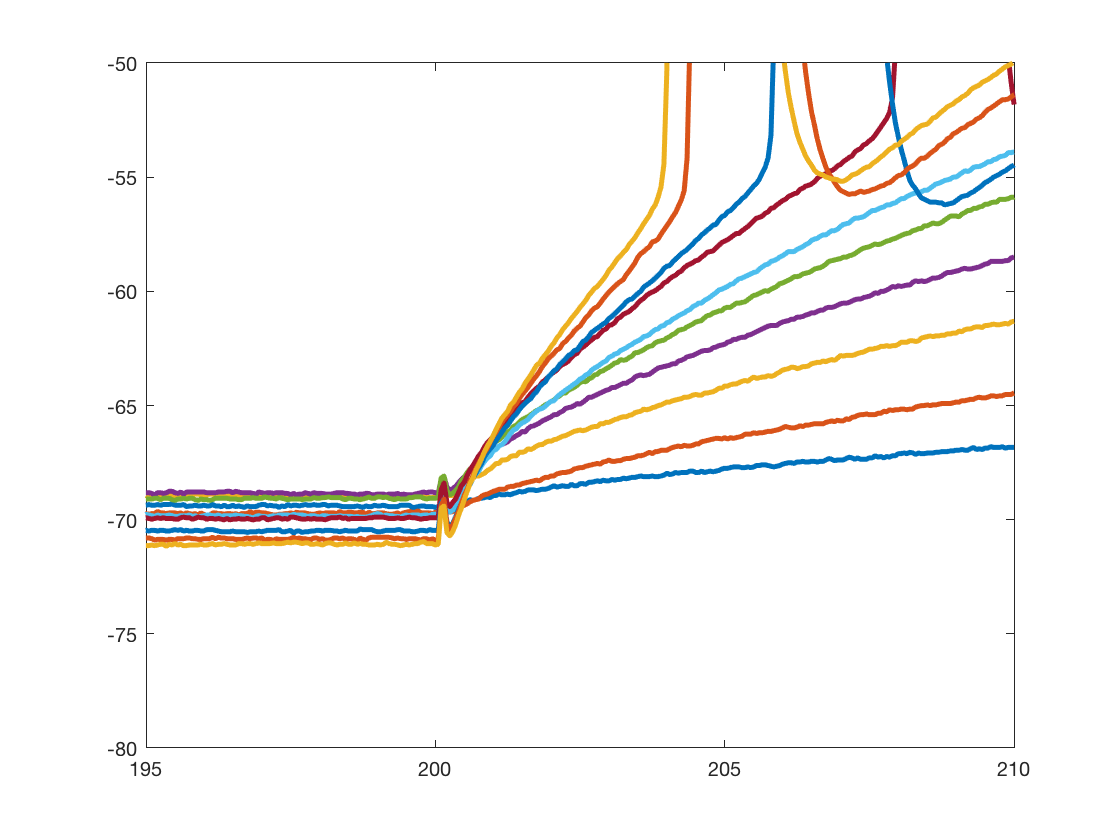



figure;
plot(t,in,'LineWidth',2.5);
xlim([195 210]);
ylim([-80 -50]);

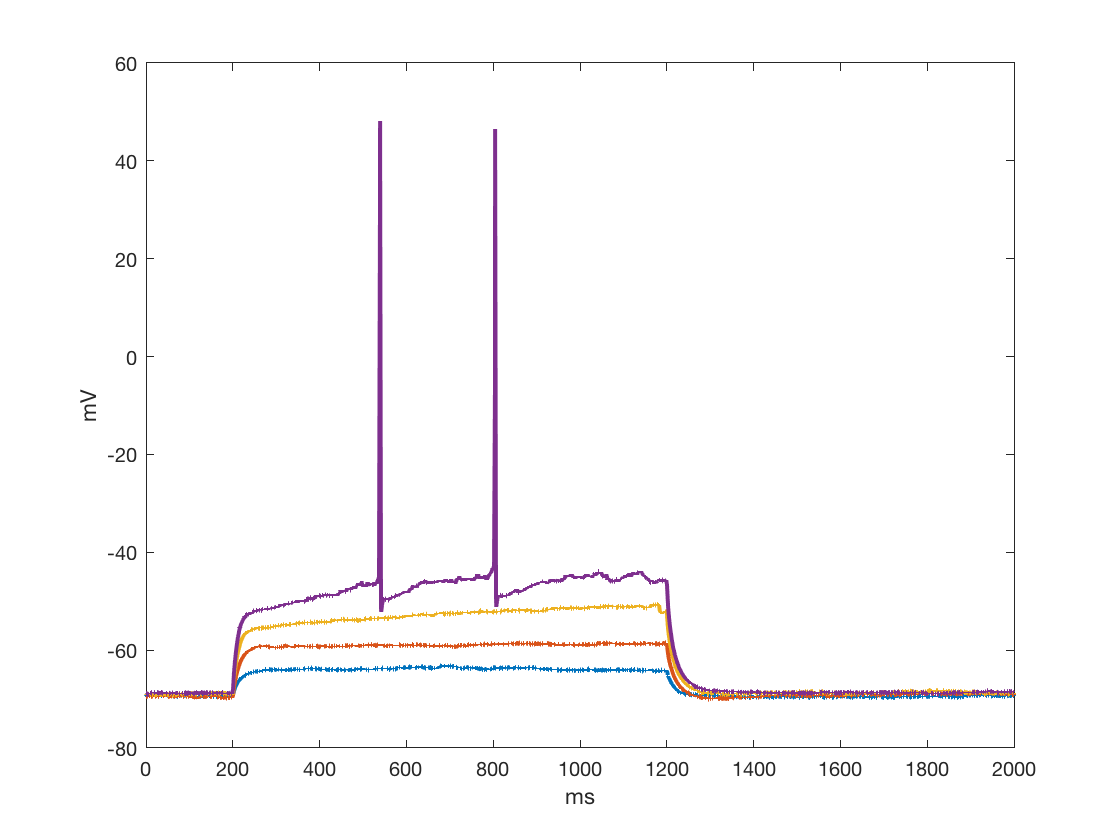



figure;             
plot(t,in(1:4,:),'LineWidth',2);
ylabel('mV');
xlabel('ms');

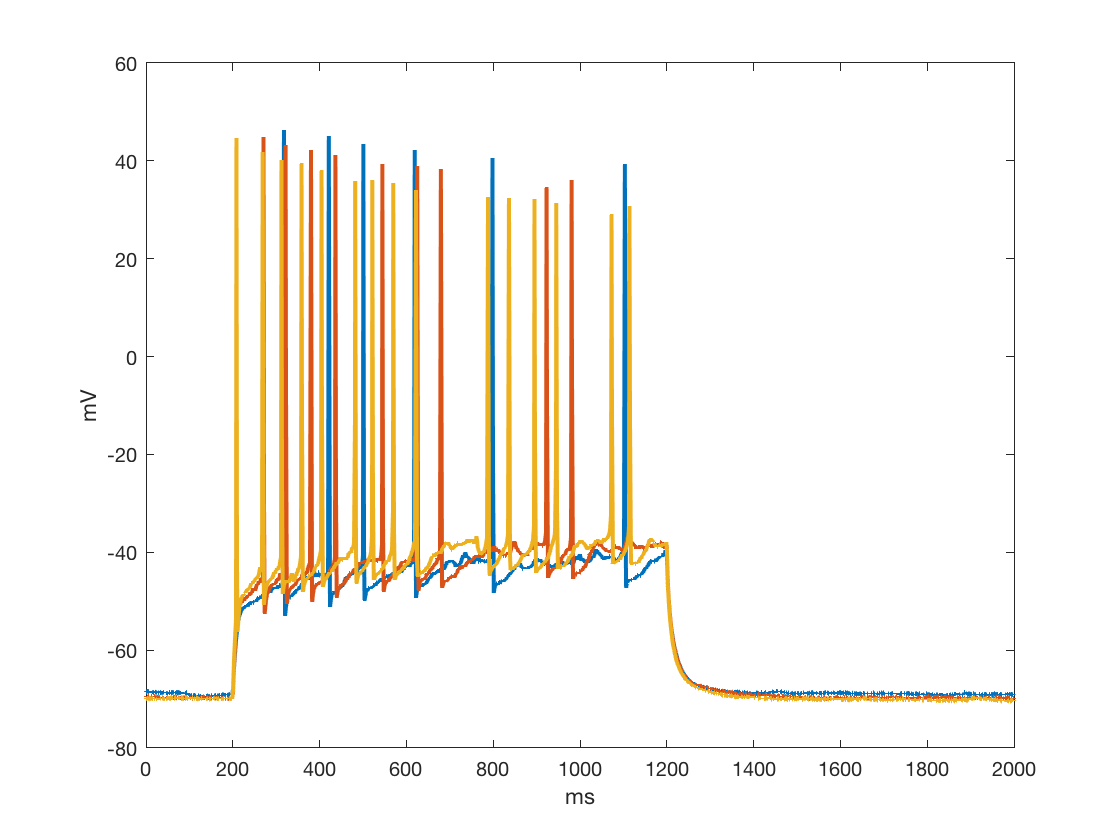

figure;
plot(t,in(5:7,:),'LineWidth',2);
ylabel('mV');
xlabel('ms');

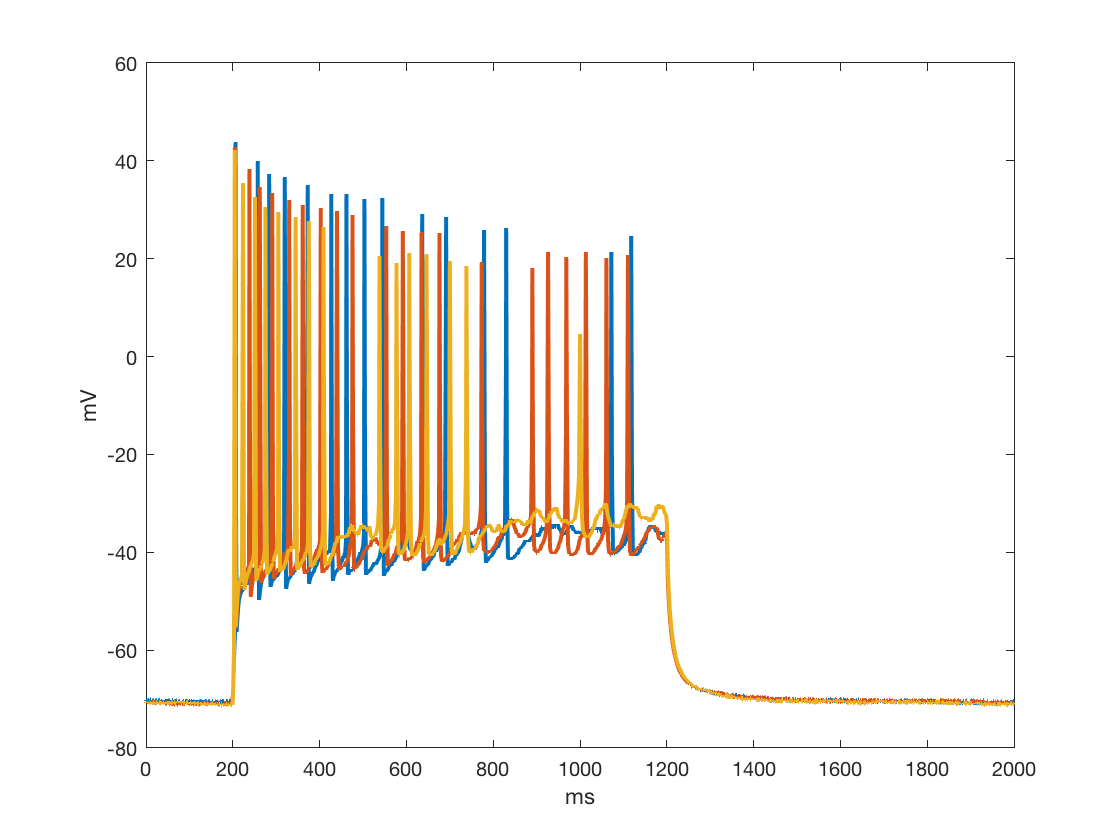

plot(t,in(8:10,:),'LineWidth',2);
ylabel('mV');
xlabel('ms');

## baseline sweeps



for k = 1:10
    baseline(k) = mean(in(k,3400:4000));
end

a = baseline';
in_baselined = in - a;





## count and locate peaks



ii = 1;

Fs = 20000;


spikes = NaN(10,1);

for ii = 1:10
    
    [PKS,LOCS] = findpeaks(in_baselined(ii,:),Fs,'MinPeakHeight',60,'MinPeakDistance',0.006);
    
    if LOCS > 0
        
        spikes(ii) = length(LOCS);
        
    else
        spikes(ii) = 0;
        ii = ii+1;
    end
end


clear ii Fs

%spikes = spikes';
a = spikes

a =      0
     0
     0
     2
     6
     9
    15
    15
    20
    15
